# Torsión en barras con perfiles cuadriculados

clc
clear all %#ok<*CLALL>

mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
[pathstr,~,~] = fileparts(mfilePath);
cd(pathstr)

PYTHON_EXEC="python.exe";
profiles_dir = "perfiles";
profile_files = get_profile_files(profiles_dir);

% Para MATLAB (R2022b) New Desktop Plugin 
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue= 'light';
 

**Crear nuevo perfil**

new_profile_name = "profile_1";
ncells = 10;
if ~exist(profiles_dir, 'dir')
   mkdir(profiles_dir)
end
output = sprintf("%s/%s", profiles_dir, new_profile_name);
system(sprintf("%s profile_designer.py %s %d", PYTHON_EXEC, output, ncells));
if ~contains(profile_files, new_profile_name)
    profile_files(end+1) = sprintf("%s.pbm", new_profile_name);
end
 

**Seleccionar perfil**

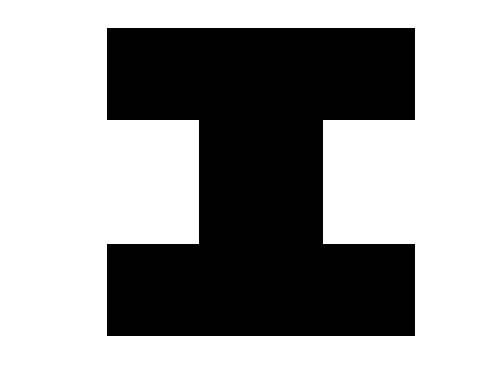

profile_name = "i";
profile_ext = "pbm";
profile_file = sprintf("%s/%s.%s", profiles_dir, profile_name, profile_ext);
profile_data = imread(profile_file) > 0;
imshow(imresize(profile_data, 5, "nearest"))

**Parámetros**

params = struct();
params.T = 8000; % torque [N*mm]
params.W = 10; % ancho perfil [mm]
params.L = 100; % longitud perfil [mm]
params.G = 80; % modulo de rigidez cortante material [GPa]
params.h = 0.1; % (dx) tamaño de malla [mm]
 

**Solucionar sistema**

 
ts = torsionsys(~profile_data, params);
tic
ts = ts.setupsystem();
tset = toc;
tic
ts = ts.solvesystem();
tsol = toc;
disp("¡Hecho!")

¡Hecho!


disp(params)

    T: 8000
    W: 10
    L: 100
    G: 80
    h: 0.1000



disp("Resultados")

Resultados


fprintf("Tiempo creación sistema: %0.3f segs\n", tset)

Tiempo creación sistema: 0.155 segs


fprintf("Tiempo solución sistema: %0.3f segs\n", tsol)

Tiempo solución sistema: 0.183 segs


fprintf("Ángulo theta: %0.2e rads (%0.4f°)\n", ts.theta, rad2deg(ts.theta))

Ángulo theta: 3.14e-03 rads (0.1799°)


**Gráficas sección**

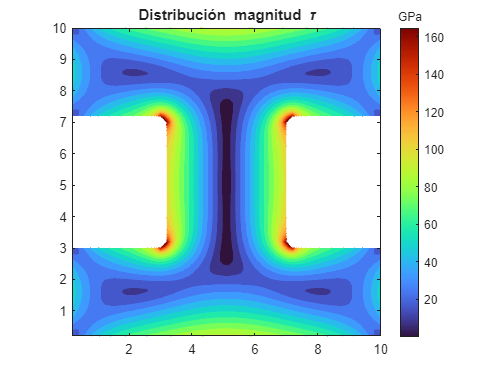

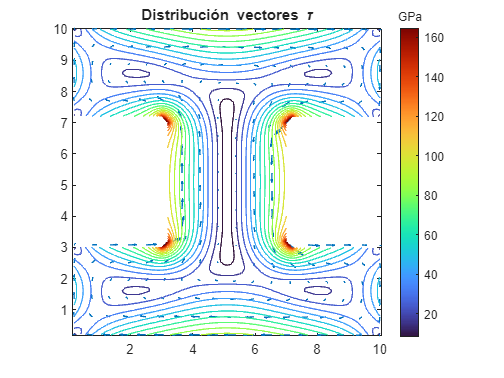

showtau = true;
showtauxy = false;
showPhi = true;
 

if ~(showtau || showtauxy || showPhi)
    disp("Gráficas distribución deshabilitadas")
end
if showtau
    ts.showtau();
    ts.showtaucamp();
end

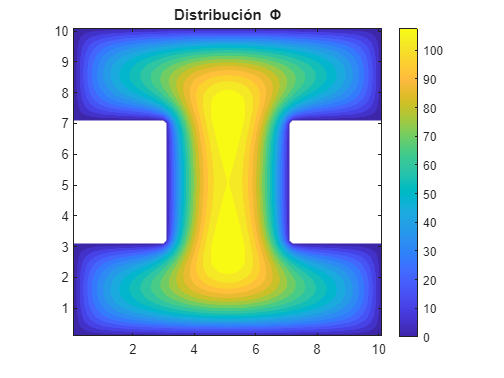

if showtauxy
    ts.showtaucomps();
    %ts.showtauxz()
    %ts.showtauyz()
end
if showPhi
    ts.showPhi()
end

function profile_files = get_profile_files(profiles_dir)
    profile_files = struct2cell(dir(sprintf("%s/*.ppm",profiles_dir)));
    profile_files = string(profile_files(1,:));
end